# **Adjustment for Non_Linear GM L2**

%Unknown X, Residual
addpath Template_data\
addpath Function\
clearvars
warning('off')

**Input Data (Copy here only)**

addpath Semester_2nd_data\
 
Elist=["Free_=|Ext('8series2_1.txt','xa','1st')|Ext('8series2_2.txt','xb','1st')|"
    "Free_data=[Ext('8series2_1.txt','xa','1st');Ext('8series2_2.txt','xb','1st')]"
    "L_=|Ext('8series2_1.txt','ya','2st')|Ext('8series2_2.txt','yb','2st')|"
    "L_data=[Ext('8series2_1.txt','ya','2st');Ext('8series2_2.txt','yb','2st')]"
    "X_=|a|b|"
    "X_data=[1;0.3]"];
AnalyzeEList(Elist);
% Stochastic

VCE_CONFIG=true;
[Var_ind,Var_name]=findVar();
S_L=expand_V(ones(size(L_)),Var_ind,u2u("1m 1m")); 

% Function
F_=[a*xa+b;
    a*xb+b];

**2. Setup your Output and Threshold**

VCE_CONFIG=false; %Variance Component Estimation
epsilon = 10^-5; %Convergence
delta = 1e-9; %Convergence
L_Config=false;  %display output for L
SLL_Config=false; %display output for S
Func_Config=true; %display output for Function Model
Cons_Config=true; %display output for Constrint
A_Config=false; %display output for Design Matrix
Obs_Config=true; %display output for Observation


## **1. Gaussian Markov Model**

**Preprocess**

checkConfig();

The angle in L_. 
No angle Detected
The angle in X_. 
No angle Detected


if ~isempty(L_i)
    F_m=F_;
    F_m(L_i)=mod(F_(L_i),2*pi);
else
    F_m=F_;
end
%Number of observations
no_n =  length(L_); 
%Number of unknowns
no_u = length(X_);
%Redundancy
redundancy = no_n-no_u;

**Function and Observation**

if ~exist("dash")
    dash=[0];
end
L_dash_=L_+dash;
F_=F_+dash;   
F_m=F_m+dash;
if L_Config
    disp("=========================")
    disp("1. Observation Vector (Observation)") 
    disp("=========================")
    L_==L_data+dash    %Show here
end

**Stochastic Model**


sigma_0 =1;
if ~exist("S_LL")
    S_LL = diag(S_L.^2);     %Show here
end
if ~exist("S_L")
    S_L = diag(S_LL);       %Show here
end

Q_LL = 1/sigma_0^2*S_LL;
P_LL = inv(Q_LL); 

if SLL_Config
    disp("=========================")
    disp("2. Stochastic Model (SLL/P)") 
    disp("=========================")
    diag(L_.^2)  %Show here
end

**Constraint**

if exist("cons_info","var")

    B_=cons_info{1};
    if ~isempty(cons_info{2})
        FB_=cons_info{2};
    end
       %Show Here
    no_b=size(B_);
    no_b=no_b(1);
    redundancy = no_n-no_u+no_b;
end
if Cons_Config
    if exist("cons_info","var")
        disp("=========================")
        disp("3.Constraint Model (Constraint Model)") 
        disp("=========================")
        display(cons_info{4})
        Cons_model=FB_==LB_data    %Show Here
        B_
    end
end
 

**Function Model**

if Func_Config
    disp("=========================")
    disp("3.Function Model (Redundancy, Function)") 
    disp("=========================")
    L_dash_==F_   %Show Here
    redundancy  %Show Here
    disp("if There exist unknow in function model, then it will be NL")
    disp("if not it will be Linear")
end 

3.Function Model (Redundancy, Function)


redundancy =    200


if There exist unknow in function model, then it will be NL


if not it will be Linear


**Observation **

V_=F_-L_dash_;
A_=jacobian(V_,X_);  %Show Here
if A_Config
    disp("=========================")
    disp("4. Design Matrix") 
    disp("=========================")
    A_
end
if Obs_Config
    disp("=========================")
    disp("5.Observation Equation(Objective)") 
    disp("=========================")
 
    disp("O=vTPv--->min")   %Show Here
    V_ 
end

5.Observation Equation(Objective)


O=vTPv--->min


**Input Data**

% 6.Measurement L
Ndeal(L_, L_data)
% 7.Free Error X
Ndeal(Free_, Free_data)
% 8.Initial values for the unknowns
Ndeal(X_, X_data)
if exist("LB_","var"),Ndeal(LB_, LB_data); end
if exist("X_O","var"),Ndeal(X_O, X_data); end
 

## **2. Adjustment**

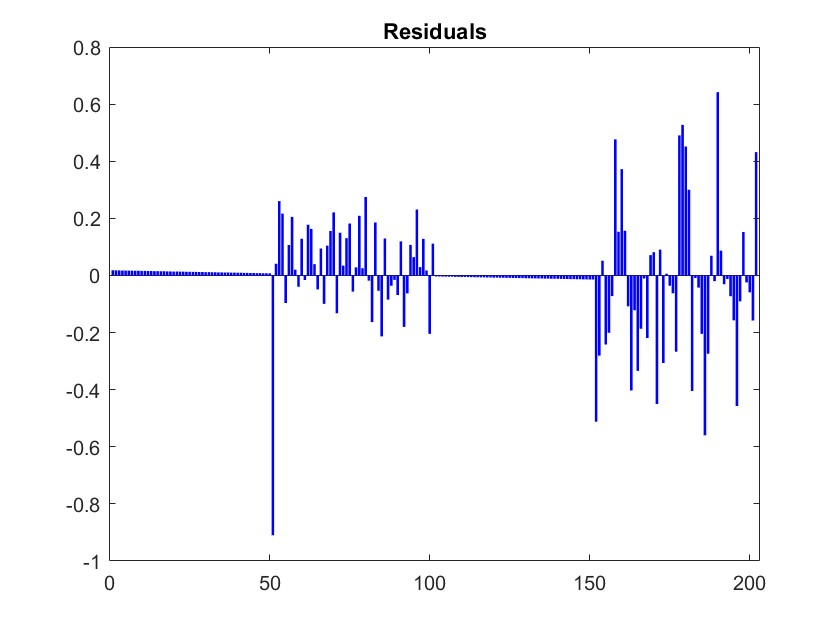


L_0=eval(L_);
V_0=eval(V_);
L_dash_0=eval(L_dash_);
X_0=eval(X_);
L_dash_hat=eval(L_dash_);

%break-off conditions
epsilon = 10^-5;
delta = 1e-9;
iteration = 0;
max_xsmall_hat=10^Inf;
syms thx
safe=thx;
thx=0;
checkVCE=true;
vce_iter=0;

if VCE_CONFIG==true
% initial values
    a_all=expand_V(zeros(size(L_)),Var_ind,1*ones(length(Var_ind),1));
    s_o_all=expand_V(zeros(size(L_)),Var_ind,10^10*ones(length(Var_ind),1));
end
%VCE
while checkVCE
    vce_iter=vce_iter+1;
    
    if VCE_CONFIG==true
        %Iteration 1
        checkVCE=sum(abs(s_o_all-1)>10^-4)~=0;
        %VC Matrix of the observations
        C_LL_all=diag(a_all.^2.*S_L.^2);
        %Cofactor matrix of the observations
        Q_LL=1/sigma_0^2*C_LL_all;
        P_LL = inv(Q_LL); 
    else
        checkVCE=0;
    end
        
    max_xsmall_hat=10^Inf;
    while  max_xsmall_hat>epsilon || max(abs(L_dash_hat-eval(F_m)))>delta
        if iteration==20
            disp("Lower down the delta to 1e-10, eps to 1e-8")
            delta=1e-8;
        elseif iteration==30
            disp("Lower down the delta to 1e-7, eps to 1e-5")
            delta=1e-7;
        end
        iteration=iteration+1;
        A_evl=eval(A_+safe);
        l_vec=L_dash_0-eval(F_m); % vector of reduced observation
    
        %Normal matrix
        N = A_evl'*P_LL* A_evl; 
        n = A_evl'*P_LL*l_vec;
        if exist("cons_info","var")
            
     
            if cons_info{3}=="B"
                B_evl=eval(B_+safe);  
                n_ext = [n;zeros(no_b,1)];
                
            elseif cons_info{3}=="G"
                B_evl=eval(B_+safe);  
                n_ext = [n;zeros(no_b,1)];
                
            elseif cons_info{3}=="g_inv"
                B_evl=eval(B_+safe);  
                n_ext = [n;zeros(no_b,1)];
                
            elseif cons_info{3}=="pseudo"
                [v lambda] = eig(N); 
                B_evl=v(:,find(diag(lambda)<0.000001))';
                no_b=size(B_evl);
                no_b=no_b(1);
                redundancy = no_n-no_u+no_b;
                n_ext = [n;zeros(no_b,1)];
                
            elseif cons_info{3}=="fullrank"
                B_evl=eval(B_+safe);  
                n_ext = [n;eval(LB_)-eval(FB_)];
            else
                error("flag is not right")
        
            end
            
            N_ext=[N B_evl';B_evl zeros(no_b,no_b)];
            Q_xx_ext = inv(N_ext);
            %n_ext = [n;zeros(no_b,1)];
            
            %Inversion of normal matrix / Cofactor matrix of the unknowns
            
            Q_XX = Q_xx_ext(1:no_u,1:no_u);    
            %Solution of normal equation
            X_smallhat=Q_xx_ext*n_ext;  
            max_xsmall_hat=max(abs(X_smallhat(1:no_u)));
            V_hat = A_evl*X_smallhat(1:no_u)-l_vec;
            Ndeal(X_,X_smallhat(1:no_u)+eval(X_));
        else
            %Vector of right hand side of normal equations
            
            %Inversion of normal matrix / Cofactor matrix of the unknowns
            Q_XX = inv(N);    
            %Solution of normal equation
            X_smallhat=Q_XX*n;     
            max_xsmall_hat=max(abs(X_smallhat));
            Ndeal(X_,X_smallhat+eval(X_));
            V_hat = A_evl*X_smallhat-l_vec;
            
        end
        
        V_hat_rad=V_hat;
        % Update v
        Ndeal(L_,L_0+V_hat);
        
        L_dash_hat = L_dash_0+V_hat;
        L_hat=L_0+V_hat;
        X_hat=eval(X_);
        Ndeal(X_O,X_hat);
        %Objective function
        vTPv = V_hat'*P_LL*V_hat;
    
        if iteration > 35
            error("Wrong")
        elseif vce_iter > 20
            error("Wrong VCE")
        end
    end
     
    %Empirical reference standard deviation
    s_0 = sqrt(vTPv/(redundancy));     %a posteriori
    %VC matrix of adjusted unknowns
    S_XX_hat = s_0^2*Q_XX;
    %Cofactor matrix of adjusted observations
    Q_LL_hat = A_evl*Q_XX*A_evl';
    %VC matrix of adjusted observations
    S_LL_hat = s_0^2*Q_LL_hat;
    %Cofactor matrix of the residuals
    Q_vv = Q_LL-Q_LL_hat;
    %VC matrix of residuals
    S_vv = s_0^2*Q_vv;
    
    S_v=sqrt(diag(S_vv));
    S_X=sqrt(diag(S_XX_hat));
    S_L_hat=sqrt(diag(S_LL_hat));
    
    %Check VCE 
    Q_vvP = Q_vv*P_LL;
    if VCE_CONFIG==true       %~exist("Var_ind")
        %[Var_ind,Var_name]=findVar();

        for i =1:length(Var_ind)
            P_dist=P_LL(Var_ind{i},Var_ind{i});
            Q_vvP_dist=Q_vvP(Var_ind{i},Var_ind{i});
            %Sub-vectors of residuals
            v_dist = V_hat_rad(Var_ind{i},1);          %sub-vector of v
            %Compute trace for sub-matrices Q_vvP_dist and Q_vvP_dir
            r_dist = trace(Q_vvP_dist);
            s_o_dist(i,1) =sqrt((v_dist'*P_dist*v_dist)/r_dist);
        end
 
        s_o_all=expand_V(zeros(size(L_)),Var_ind,s_o_dist);
        a_all=a_all.*s_o_all;
    end

end

if exist("cons_info",'var')
    rank_deficient=size(N);
    rank_deficient=rank_deficient(1)-rank(N)
    check_condition=LB_data-eval(FB_)
end


if exist("list_info") && length(list_info)==3
            [X_hat,useless]=normalizeX_(X_hat,"inverse",list_info);
            [X_0,useless]=normalizeX_(X_0,"inverse",list_info);
            Ndeal(X_,X_hat);
end
            
%plotxyc(X,L_dash,eval(F_))
figure
bar(V_hat,"b")
title("Residuals")


%Final check
if abs(L_dash_hat-eval(F_m))<delta
    disp("Good")
else
    disp("Wrong")
end

Good


**Get X, L, and residual.**

%Conversion
if exist("X_i",'var')
    X_hat(X_i)=mod(X_hat(X_i)*200/pi,400);
    S_X(X_i)=S_X(X_i)*200/pi;
end    
if exist("L_i",'var')
    L_0(L_i)=L_0(L_i)*200/pi;
    L_dash_hat(L_i)=mod(L_dash_hat(L_i)*200/pi,400);
    L_hat(L_i)=mod(L_hat(L_i)*200/pi,400);
    S_L_hat(L_i)=S_L_hat(L_i)*200/pi;
    V_hat(L_i)=V_hat(L_i)*200/pi;
    S_v(L_i)=S_v(L_i)*200/pi;
end
format long


disp("Get Unknown X_hat, S_x:") 

Get Unknown X_hat, S_x:


Unknown=arrayfun(@(x) sprintf("%s",x),X_);
table(Unknown,X_0,X_hat,S_X)

ans = 2×4 table
    Unknown    X_0          X_hat                  S_X        
    _______    ___    __________________    __________________

      "a"        1     0.989153150034946    0.0104554960430648
      "b"      0.3    0.0280821751582192    0.0261021863094964



disp("Get Updated L_hat, S_l:") 

Get Updated L_hat, S_l:


Measurment=arrayfun(@(x) sprintf("%s",x),L_);
table(Measurment,L_0,L_hat,L_dash_hat,S_L_hat,["V_"+(1:length(V_hat))'],V_hat,S_v)

ans = 202×8 table
    Measurment    L_0           L_hat               L_dash_hat             S_L_hat           Var6           V_hat                  S_v       
    __________    ____    __________________    __________________    __________________    ______    __________________    _________________

      "ya1"       0.01    0.0280821751582192    0.0280821751582192    0.0261021863094964    "V_1"     0.0180821751582192    0.166912391048982
      "ya2"       0.03    0.0478652381589181    0.0478652381589181    0.0259161922536492    "V_2"     0.0178652381589181    0.166941371130394
      "ya3"       0.05     0.067648301159617     0.067648301159617     0.025730553154539    "V_3"      0.017648301159617    0.166970084297114

**Get VCE Result**


if VCE_CONFIG==false       %~exist("Var_ind")
    [Var_ind,Var_name]=findVar();

    for i =1:length(Var_ind)
        P_dist=P_LL(Var_ind{i},Var_ind{i});
        Q_vvP_dist=Q_vvP(Var_ind{i},Var_ind{i});
        %Sub-vectors of residuals
        v_dist = V_hat_rad(Var_ind{i},1);          %sub-vector of v
        %Compute trace for sub-matrices Q_vvP_dist and Q_vvP_dir
        r_dist = trace(Q_vvP_dist);
        s_o_dist(i,1) =sqrt((v_dist'*P_dist*v_dist)/r_dist);
    end

    s_o_all=expand_V(zeros(size(L_)),Var_ind,s_o_dist);
    a_all=expand_V(zeros(size(L_)),Var_ind,1*ones(length(Var_ind),1));
    a_all=a_all.*s_o_all;
    
end
    

try
    disp("Variance Component") 
    a_all_dist=unique(a_all);
    table(Var_name,s_o_dist,a_all_dist) 
catch

    table(Measurment,s_o_all,a_all) 
end

Variance Component


ans = 2×3 table
    Var_name        s_o_dist            a_all_dist    
    ________    _________________    _________________

      "ya"      0.132164700562658    0.132164700562658
      "yb"      0.198975540071474    0.198975540071474


## **3. Quality Assessment**

**Global test**

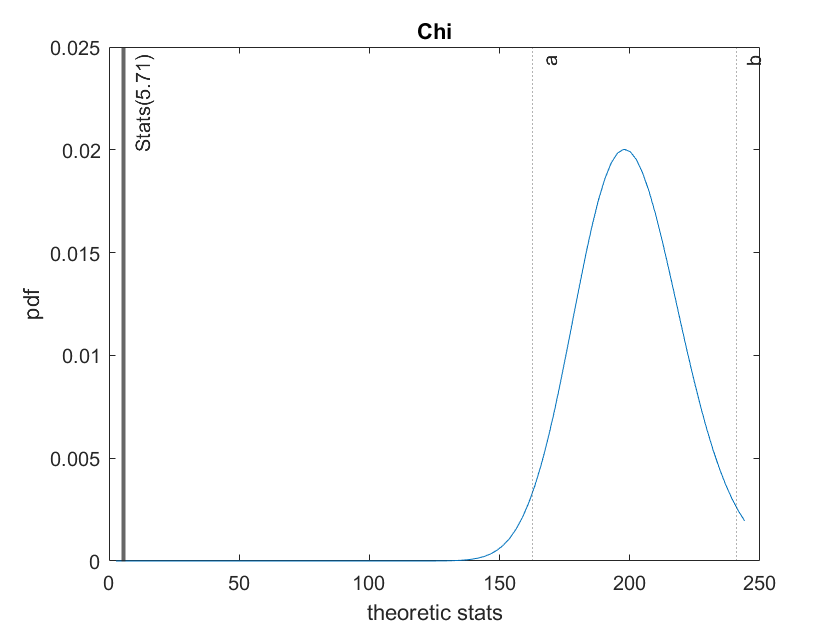

Test Statistic: 5.71 ,Critical value=[162.73,241.06]
1.Reject the null hypothesis H0: Same
1.Reject HC: Significant bigger with S=97.50%
2.Choose hypothesis HA: Significant Smaller with S=97.50%
2,Choose hypothesis HB: Significant difference with S=95.00%


try
    confidence_tool=confidence_tool();
    stats=confidence_tool.statistic_test_chi(0.975, sigma_0, s_0, redundancy);
catch
end


disp("Internal and external reliability parameters") 

Internal and external reliability parameters



%Check 3σ rule
mat=sqrt(S_L_hat);  

%Compute EV
r_i=diag(Q_vv*P_LL);
EV=r_i*100;

% NV
sigma_v=sigma_0*sqrt(diag(Q_vv));
NV=abs(V_hat_rad)./sigma_v;


for j=1:size(mat)
    % 3 sigma update
    if V_hat_rad(j)>(3*mat(j)) || V_hat_rad(j)<(-3*mat(j))
        sigma3_rule(j,1)="exceed 3sigma";
    else
        sigma3_rule(j,1)="Good";
    end
    % EV update
    if EV(j)<1
        EV_comment(j,1)="not controlled";
    elseif EV(j)<10
        EV_comment(j,1)="poorly controlled";
    elseif EV(j)<30
        EV_comment(j,1)="sufficiently controlled";
    elseif EV(j)<70
        EV_comment(j,1)="good controlled";   
    else
        EV_comment(j,1)="Excellent";   
    end
    
    % NV
    if NV(j)<2.5
        NV_comment(j,1)="no blunder";
    elseif NV(j)<4
        NV_comment(j,1)="blunder possible";
        blunder=true;
    else
        NV_comment(j,1)="blunder highly"; 
        blunder=true;
    end  
    
end



% Potential magnitude of a blunder
GF=-V_hat_rad./r_i;
 
% Lower boundary value for blunders
GRZW=ones(no_n,1); % help matlab with memory by making a empty matrix
for i=1:no_n
    GRZW(i,1)=sigma_0*4.13/sqrt(r_i(i,1)*P_LL(i,i));
end



GF(L_i,1) = GF(L_i,1)*200/pi;

GRZW(L_i,1)=GRZW(L_i,1)*200/pi;   % we change those measurments that were  amgles


P_diag=diag(P_LL);
dd=ones(size(r_i));
rw=zeros(size(r_i));


for i=1:length(L_i)
    target_name=Measurment(L_i(i));
    target_name=regexp(target_name,'\d*\.?\d*','match');
    num_1=target_name{1};
    num_2=target_name{2};
    
    %get dis
    if exist(["DIS"+num_1+"_"+num_2])
        dd(L_i(i))=eval(["DIS"+num_1+"_"+num_2]);
    elseif exist(["DIS"+num_2+"_"+num_1])
        dd(L_i(i))=eval(["DIS"+num_2+"_"+num_1]);
    else
        warning("there is no "+["DIS"+num_2+"_"+num_1])
        dd(L_i(i))=1;
    end
    Psum_i=find(contains(Measurment,["DIR"+num_1+"_"]));
    PSum=sum(P_diag(Psum_i));
    rw(L_i(i))=P_diag(L_i(i))/PSum;
end

r_i_w=1-r_i;
r_i_w=(r_i_w-rw).*dd;

EP=r_i_w.*GF;
EGK=r_i_w.*GRZW;
[mValue , vIndex] =max(V_hat_rad);
blunderstr=Measurment(vIndex);


**Interior and exterior Check**

table(Measurment,V_hat_rad,S_L_hat,sigma3_rule,EV,EV_comment,GF,GRZW,NV,NV_comment,EP,EGK)

ans = 202×12 table
    Measurment        V_hat_rad              S_L_hat          sigma3_rule           EV           EV_comment             GF                   GRZW                  NV             NV_comment              EP                     EGK        
    __________    __________________    __________________    ___________    ________________    ___________    ___________________    ________________    __________________    ____________    _____________________    __________________

      "ya1"       0.0180821751582192    0.0261021863094964      "Good"       97.6128290908181    "

**Lagrange Multiplier**

if exist("cons_info","var")
try 
disp("Show Lagrange Multiplier")
X_smallhat(no_u+1:length(X_smallhat))
catch
disp("No Lagrange Multiplier")
end  
end

**Blunder Detector**

if exist("blunder")
    disp("========================================================================")
    disp("========================================================================")
    disp("There exist blunder point, pls remove the point: "+blunderstr)
    disp("The residual is : "+num2str(mValue))
    disp("========================================================================")
    disp("========================================================================")
end